# Introduction to Data Analysis with MATLAB

In this live script, we look at some basic data handling and analysis tasks that can be done using MATLAB.

We will be using the credit card approval prediction task dataset available on kaggle. 

Link: https://www.kaggle.com/datasets/rikdifos/credit-card-approval-prediction?resource=download&select=credit_record.csv

## Importing Data

We use the function generated using the "Import Data" tool available in the Home Tab.

We will import the data into a table named data.

data = importfile("C:\Users\asus\Desktop\MATLAB Session\data\application_record.csv", [2, 2000]);
data

data = 1999×18 table
        ID        CODE_GENDER    FLAG_OWN_CAR    FLAG_OWN_REALTY    CNT_CHILDREN    AMT_INCOME_TOTAL      NAME_INCOME_TYPE           NAME_EDUCATION_TYPE          NAME_FAMILY_STATUS     NAME_HOUSING_TYPE    DAYS_BIRTH    DAYS_EMPLOYED    FLAG_MOBIL    FLAG_WORK_PHONE    FLAG_PHONE    FLAG_EMAIL    OCCUPATION_TYPE    CNT_FAM_MEMBERS
    __________    ___________    ____________    _______________    ____________    ________________    ____________________    _____________________________    ____________________    <s

## Properties of Table

We can access the properties of the table as follows:

data.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×18 cell}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


data.Properties.VariableNames           %Column names

ans = 1×18 cell array
    {'ID'}    {'CODE_GENDER'}    {'FLAG_OWN_CAR'}    {'FLAG_OWN_REALTY'}    {'CNT_CHILDREN'}    {'AMT_INCOME_TOTAL'}    {'NAME_INCOME_TYPE'}    {'NAME_EDUCATION_TYPE'}    {'NAME_FAMILY_STATUS'}    {'NAME_HOUSING_TYPE'}    {'DAYS_BIRTH'}    {'DAYS_EMPLOYED'}    {'FLAG_MOBIL'}    {'FLAG_WORK_PHONE'}    {'FLAG_PHONE'}    {'FLAG_EMAIL'}    {'OCCUPATION_TYPE'}    {'CNT_FAM_MEMBERS'}


height(data)            %number of rows

ans = 1999

width(data)             %number of columns

ans = 18

## Basic Preprocessing and Visualisation

Sorting the table according to total income and moving the column.

data = sortrows(data,'AMT_INCOME_TOTAL','descend');
data = movevars(data,'AMT_INCOME_TOTAL','After','CODE_GENDER');
head(data,3)

        ID        CODE_GENDER    AMT_INCOME_TOTAL    FLAG_OWN_CAR    FLAG_OWN_REALTY    CNT_CHILDREN      NAME_INCOME_TYPE      NAME_EDUCATION_TYPE    NAME_FAMILY_STATUS     NAME_HOUSING_TYPE     DAYS_BIRTH    DAYS_EMPLOYED    FLAG_MOBIL    FLAG_WORK_PHONE    FLAG_PHONE    FLAG_EMAIL    OCCUPATION_TYPE    CNT_FAM_MEMBERS    Is_Employed
    __________    ___________    ________________    ____________    _______________    ____________    ____________________    ___________________    __________________    _____

figure('Name','Gender Histogram')
h = histogram(data.CODE_GENDER)

h =   Histogram with properties:

              Data: [1999×1 categorical]
            Values: [1319 680]
    NumDisplayBins: 2
        Categories: {'F'  'M'}
      DisplayOrder: 'data'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


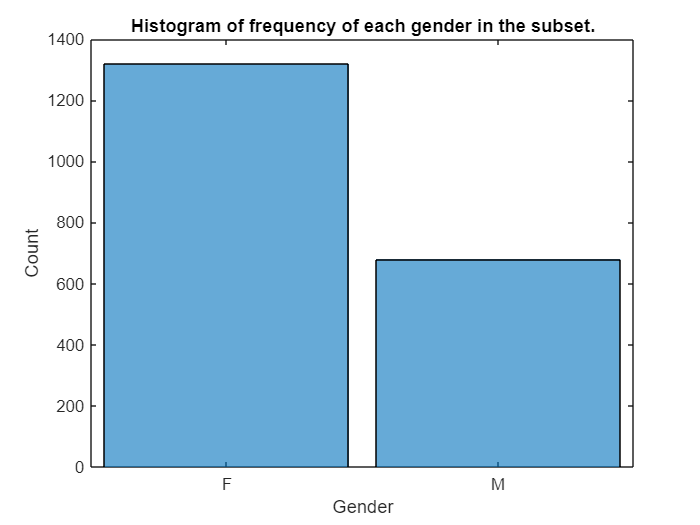

xlabel('Gender');
ylabel('Count');
title('Histogram of frequency of each gender in the subset.');

counts = h.Values;
fprintf('Number of females = %4.2f and number of men = %4.2f', counts(1), counts(2));

Number of females = 1319.00 and number of men = 680.00

h2 = histogram(data.NAME_INCOME_TYPE,"Orientation","horizontal","DisplayOrder","ascend")

h2 =   Histogram with properties:

              Data: [1999×1 categorical]
            Values: [8 165 347 455 1024]
    NumDisplayBins: 5
        Categories: {'Student'  'State servant'  'Pensioner'  'Commercial associate'  'Working'}
      DisplayOrder: 'ascend'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


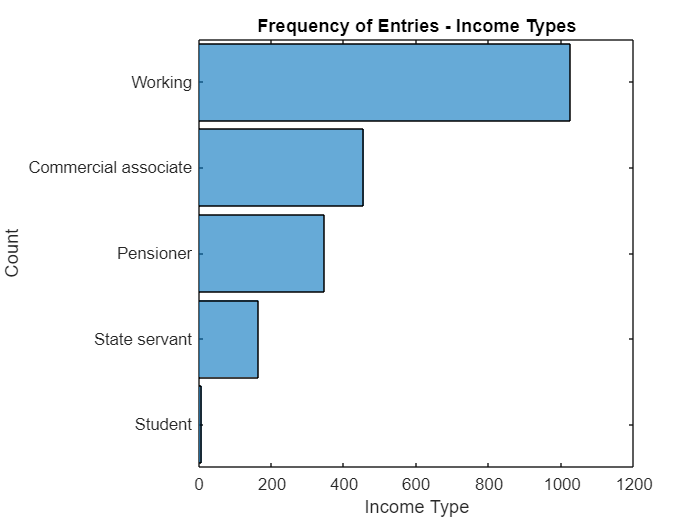

xlabel('Income Type');
ylabel('Count');
title("Frequency of Entries - Income Types");

Adding a new column to the table

data.Is_Employed = double(data.DAYS_EMPLOYED < 0);
head(data,3)

        ID        CODE_GENDER    AMT_INCOME_TOTAL    FLAG_OWN_CAR    FLAG_OWN_REALTY    CNT_CHILDREN      NAME_INCOME_TYPE      NAME_EDUCATION_TYPE    NAME_FAMILY_STATUS     NAME_HOUSING_TYPE     DAYS_BIRTH    DAYS_EMPLOYED    FLAG_MOBIL    FLAG_WORK_PHONE    FLAG_PHONE    FLAG_EMAIL    OCCUPATION_TYPE    CNT_FAM_MEMBERS    Is_Employed
    __________    ___________    ________________    ____________    _______________    ____________    ____________________    ___________________    __________________    _____

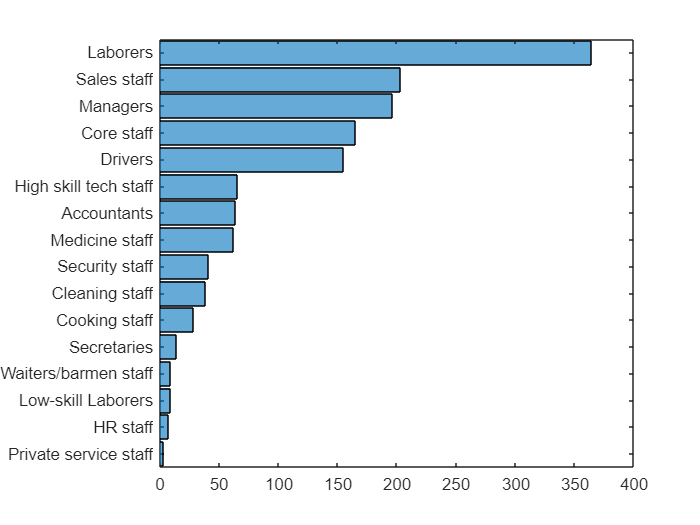

h3 =   Histogram with properties:

              Data: [1999×1 categorical]
            Values: [3 7 9 9 14 28 38 41 62 64 65 155 165 196 203 364]
    NumDisplayBins: 16
        Categories: {1×16 cell}
      DisplayOrder: 'ascend'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


h3 = histogram(data.OCCUPATION_TYPE,"Orientation","horizontal","DisplayOrder","ascend")

Finding the entries with maximum number of days of employment and maximum income.

[maxDur,idx] = mink(data.DAYS_EMPLOYED,10);
longestEmpDur = data(idx,:)

longestEmpDur = 10×19 table
        ID        CODE_GENDER    AMT_INCOME_TOTAL    FLAG_OWN_CAR    FLAG_OWN_REALTY    CNT_CHILDREN      NAME_INCOME_TYPE           NAME_EDUCATION_TYPE         NAME_FAMILY_STATUS    NAME_HOUSING_TYPE    DAYS_BIRTH    DAYS_EMPLOYED    FLAG_MOBIL    FLAG_WORK_PHONE    FLAG_PHONE    FLAG_EMAIL    OCCUPATION_TYPE    CNT_FAM_MEMBERS    Is_Employed
    __________    ___________    ________________    ____________    _______________    ____________    ____________________    _____________________________    

[maxInc,idx1] = maxk(data.AMT_INCOME_TOTAL,10);
highestInc = data(idx1,:)

highestInc = 10×19 table
        ID        CODE_GENDER    AMT_INCOME_TOTAL    FLAG_OWN_CAR    FLAG_OWN_REALTY    CNT_CHILDREN      NAME_INCOME_TYPE      NAME_EDUCATION_TYPE     NAME_FAMILY_STATUS      NAME_HOUSING_TYPE     DAYS_BIRTH    DAYS_EMPLOYED    FLAG_MOBIL    FLAG_WORK_PHONE    FLAG_PHONE    FLAG_EMAIL    OCCUPATION_TYPE    CNT_FAM_MEMBERS    Is_Employed
    __________    ___________    ________________    ____________    _______________    ____________    ____________________    ___________________    _________________

Calculate income by occupation groups

incomeByOccupation = groupsummary(data,"OCCUPATION_TYPE",["mean","std"],"AMT_INCOME_TOTAL")

incomeByOccupation = 17×4 table
       OCCUPATION_TYPE       GroupCount    mean_AMT_INCOME_TOTAL    std_AMT_INCOME_TOTAL
    _____________________    __________    _____________________    ____________________

    Accountants                  64             2.1284e+05                    90997     
    Cleaning staff               38             1.5253e+05                    61655     
    Cooking staff                28             1.0961e+05                    20828     
    Core staff                  165             1.8871e+05                    99629     
    Drivers                     155             1.8139e+05                    78622     
    HR staff                      7              2.565e+05                        0     
    High skill tech staff        65             2.2431e+05               1.3049e+05     
    Laborers                  

topincome = topkrows(incomeByOccupation,5,"mean_AMT_INCOME_TOTAL")

topincome = 5×4 table
       OCCUPATION_TYPE       GroupCount    mean_AMT_INCOME_TOTAL    std_AMT_INCOME_TOTAL
    _____________________    __________    _____________________    ____________________

    Managers                    196             3.4875e+05               2.3684e+05     
    HR staff                      7              2.565e+05                        0     
    High skill tech staff        65             2.2431e+05               1.3049e+05     
    Accountants                  64             2.1284e+05                    90997     
    Laborers                    364              2.089e+05                    71709     


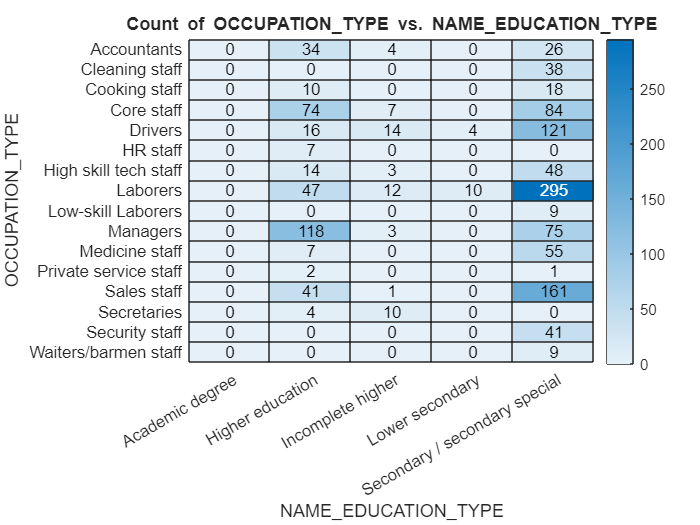

heatmap(data,"NAME_EDUCATION_TYPE","OCCUPATION_TYPE"); 

## Working with Missing Data

idx = ismissing(data);
sum(idx)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   576     0     0


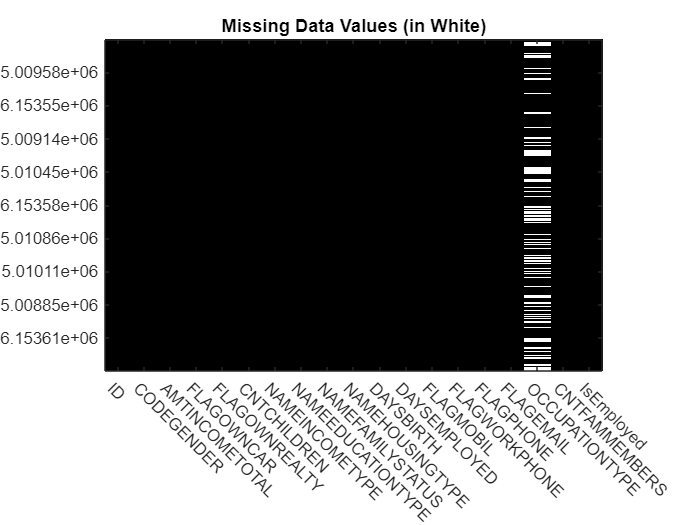

visualizeTableMask(data,idx);
title("Missing Data Values (in White)")

We observe that a significant number of entries have their OCCUPATION_TYPE missing.

## Saving the data

save data\application_record_preprocessedsubset.mat data;

function visualizeTableMask(data,idx)
figure
imagesc(idx)
xticklabels(erase(data.Properties.VariableNames,"_"))
xticks(1:width(data))
xtickangle(-45)
ys = yticks;
yticklabels(data.ID(ys))
colormap gray
end